# **Calculate M and Theta (2 equations, 2 solutions)**

On the other script ('Calculate_M_Theta_UniqueSolution_Num.mlx') we used the Optimization Toolbox to solve the equations with the same solver as in 'Calculate_M_Theta_ApproximateSolution.mlx' ('lsqnonlin') to be consistent with the 'Calculate_M_Theta_ApproximateSolution.mlx' and also in order not to use 2 Toolboxes. Here we solve the equations symbolically with the Symbolic Toolbox. It's the same, but this was the first version.

**Last Update:** 27/Jan/2020

## **Addpaths**

clear all
clc
close all
addpath(genpath('C:\Users\Rita\Documents\MATLAB\spm8'))
path ='C:\Users\Rita\Desktop\CHUV_Tests';
addpath(genpath(path))
cd(path)

## G as a function of r

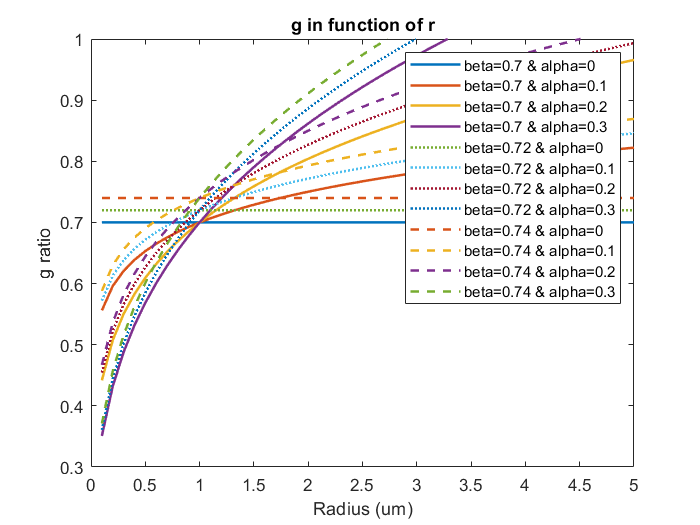

% Initiate
r       = 0.1:0.1:5;
lgd     = cell(12,1);
k       = 1;
ls = {'-','-','-','-',':',':',':',':','--','--','--','--'};

% Loop for betas and alphas
figure()
for beta=0.7:0.02:0.74
    for alpha=0:0.1:0.3
        g       = beta.*r.^alpha;
        lgd{k}  = strcat('beta=',num2str(beta),' & alpha=', num2str(alpha));
        plot(r,g,'LineStyle',ls{k},'LineWidth',1.5)
        hold on
        k       = k+1;
    end
end
xlabel('Radius (um)')
ylabel('g ratio')
ylim([0.3 1])
title('g in function of r')
legend(lgd)

## EQUATION 1 - Solve (assume theta)

% Initiate
alpha   = 0.1;
beta    = 0.7;
A       = 1.02;
g       = 0.70;
syms M
theta = 0.25;

% Make equations
[g_eqn_EasyLevel_raw, g_eqn_HardLevel,g_eqn_GammaLevel] = make_equations_g(M,theta,g,alpha,beta,A);

% Solve equations
S = vpasolve(g_eqn_EasyLevel_raw,M,[0.1,0.8])

$$S = 0.4942403384197136683062494751859$$

S = vpasolve(g_eqn_HardLevel,M,[0.1,0.8])

$$S = 0.40694675374659130507787277528796$$

S = vpasolve(g_eqn_GammaLevel,M,[0.1,0.8])

$$S = 0.39751693064990176983746681295331$$

## EQUATION 1 - Solve (assume mode)

% Initiate
alpha   = 0.1;
beta    = 0.7;
A       = 1.02;
g       = 0.70;
syms theta
M       = 0.4;

% Make equations
[g_eqn_EasyLevel_raw, g_eqn_HardLevel,g_eqn_GammaLevel] = make_equations_g(M,theta,g,alpha,beta,A);

% Solve equations
S = vpasolve(g_eqn_EasyLevel_raw,theta,[0,0.8])

$$S = 0.34878757869489740299158595339346$$

S = vpasolve(g_eqn_HardLevel,theta,[0,0.8])

$$S = 0.25305244293388023630171835218699$$

S = vpasolve(g_eqn_GammaLevel,theta,[0,0.8])

$$S = 0.24897380849125606971652728867613$$

## EQUATION 1 - Plot in function of theta and M 

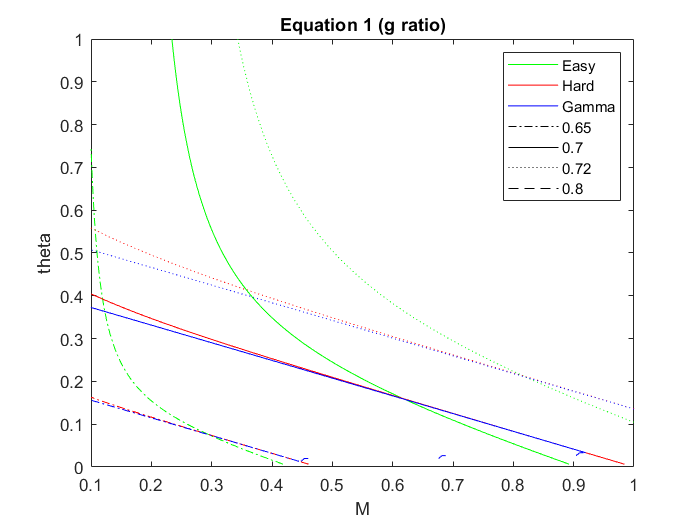

% Initiate
alpha = 0.1;
beta = 0.7;
A  = 1.02;
G = [0.65,0.72,0.8,0.70];
ls = {'-.',':','--','-'};

% Loop for different g ratios
figure()
for i=1:length(G)
g=G(i);

syms M theta
% Make equations
[g_eqn_EasyLevel_raw, g_eqn_HardLevel,g_eqn_GammaLevel] = make_equations_g(M,theta,g,alpha,beta,A);

% Plot
p1 = fimplicit(g_eqn_EasyLevel_raw,'Color','g','LineStyle',ls{i});
hold on
p2 = fimplicit(g_eqn_HardLevel,'Color','r','LineStyle',ls{i});
hold on
p3 = fimplicit(g_eqn_GammaLevel,'Color','b','LineStyle',ls{i});
end

% Plot stuff just to make legend
hold on
st1 = plot([-2,-1],[-2,-1],'Color','k','LineStyle','-.');
hold on
st2 = plot([-2,-1],[-2,-1],'Color','k','LineStyle','-');
hold on
st3 = plot([-2,-1],[-2,-1],'Color','k','LineStyle',':');
hold on
st4 = plot([-2,-1],[-2,-1],'Color','k','LineStyle','--');

xlim([0.1,1])
ylim([0,1])
xlabel('M')
ylabel('theta')
legend([p1,p2,p3,st1,st2,st3,st4],{'Easy','Hard','Gamma','0.65','0.7','0.72','0.8'})
title('Equation 1 (g ratio)')

#### Comments:

The easy approximation doesn't behave as the Hard approximation or the Gamma. 

For bigger Thetas the function "explodes". As we can see below, the lower the mode, the bigger the ratio has to be in order to represent the gamma ratio as accurate as possible.

Fixating the ratio to just one value that is constant for each mode and each theta creates a bias in the equation that is bigger for lower modes.

## Equation 1 - Sensibility Evaluation 

### 1. Easy Ratio btw 2 gammas:

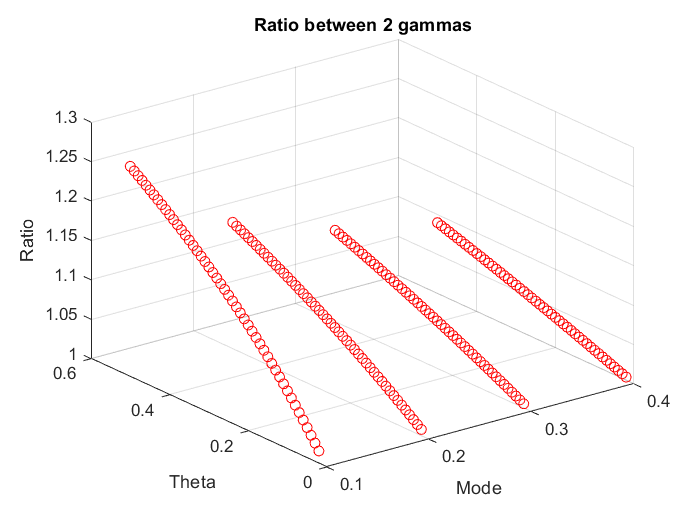

figure()
for mode=0.1:0.1:0.4
for theta=0.02:0.01:0.5
    LL      = (mode/theta)^(2*alpha); % lower limit approximation
    UL      = (mode/theta + 1)^(2*alpha); % Upper limit approximation
    TV      = gamma(mode/theta+1)/gamma(mode/theta+1-2*alpha); % true ratio between gammas
 
    ratio   = TV/LL;
    
    scatter3(mode,theta,ratio,'r')
    hold on
end
end 
xlabel('Mode')
ylabel('Theta')
zlabel('Ratio')
title('Ratio between 2 gammas')

### 2. Bias in Gamma true function:

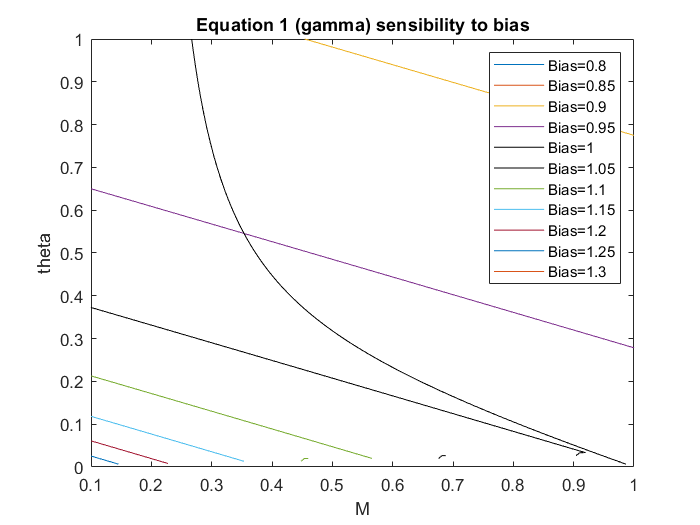

% Initiate
alpha       = 0.1;
beta        = 0.7;
g           = 0.7;
lgd         = cell(11,1);
k           = 1;
       
% Loop for different bias
figure()
for i=0.8:0.05:1.3
    Abias = i;
    syms M theta
    
    % Make equation
    [~, ~,g_eqn_GammaLevel] = make_equations_g(M,theta,g/Abias,alpha,beta,1);
    [g_eqn_EasyLevel_raw, ~,~] = make_equations_g(M,theta,g,alpha,beta,1);
    symvar(g_eqn_EasyLevel_raw); % x = M, y = theta, é definido por symvar!! E este funciona por ordem alfabética

    % Plot
    if i==1
        fimplicit(g_eqn_GammaLevel,'Color','k');
        hold on
        fimplicit(g_eqn_EasyLevel_raw,'Color','k');
    else
        fimplicit(g_eqn_GammaLevel);
        hold on
    end
    
    % Legend
    lgd{k}  = strcat('Bias=',num2str(i));
    k       = k+1;
end


xlim([0.1,1])
ylim([0,1])
xlabel('M')
ylabel('theta')
legend(lgd)
title('Equation 1 (gamma) sensibility to bias')

**Comments**:

As we can see, the lower the bias, aka, if we underestimate the ratio (that is what we are doing for lower modes if we assume a constant ratio of 1.02 for example) the bias is bigger, therefore the shift of the equation is quite big, leading to a big bias in the solution.

eg. For a mode of 0.2 (and a theta of ~0.1,), the ratio between the true value and the lower limit that we are using as an approximation is ~1.04. This means that if I don't use an accurate factor to account for the bias in the gamma ratios and use just the lower limit, we will be underestimating the solution by 1/1.04=0.96 which is an accordance with the last graph. 

The same is not true for equation 2, as we can see above.

## Equation 2 - Sensibility Evaluation 

### 1. Easy Ratio btw 2 gammas: 

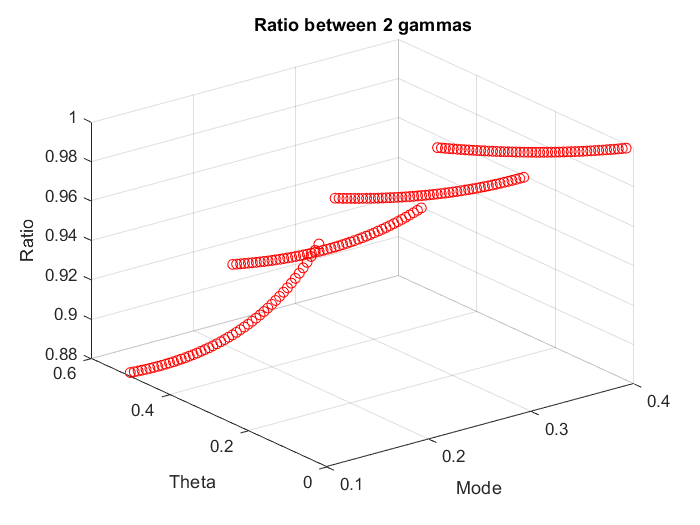

figure()
for mode=0.1:0.1:0.4
for theta=0.02:0.01:0.5
    UL      = (mode/theta)^(-alpha);
    LL      = (mode/theta + 1)^(-alpha);
    TV      = gamma(mode/theta+1-alpha)/gamma(mode/theta+1);

    ratio   = TV/UL;
    
    scatter3(mode,theta,ratio,'r')
    hold on
end
end 
xlabel('Mode')
ylabel('Theta')
zlabel('Ratio')
title('Ratio between 2 gammas')

### 2. Bias in Gamma true function:

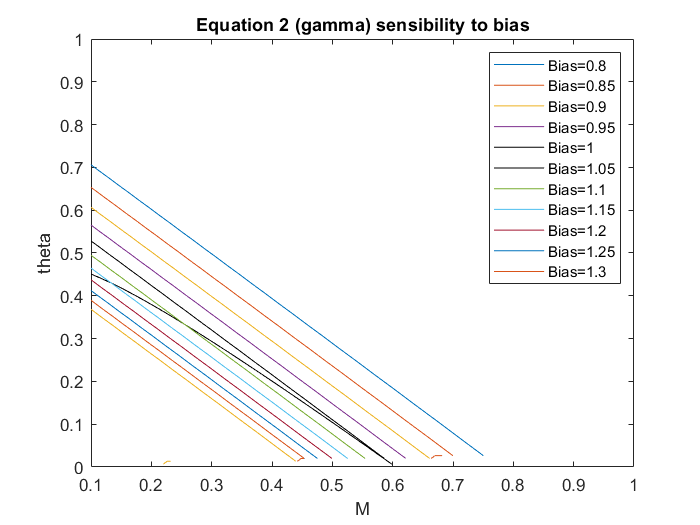

% Initiate
alpha       = 0.1;
beta        = 0.7;
v           = 10;
lgd         = cell(11,1);
k           = 1;
       
% Loop for different bias
figure()
for i=0.8:0.05:1.3
    Cbias = i;
    syms M theta
    
    % Make equation
    [~, ~,v_eqn_GammaLevel] = make_equations_v(M,theta,v/Cbias,alpha,beta,1);
    [v_eqn_EasyLevel, ~,~] = make_equations_v(M,theta,v,alpha,beta,1);
    symvar(v_eqn_EasyLevel); % x = M, y = theta, é definido por symvar!! E este funciona por ordem alfabética

    % Plot
    if i==1
        fimplicit(v_eqn_GammaLevel,'Color','k');
        hold on
        fimplicit(v_eqn_EasyLevel,'Color','k');
    else
        fimplicit(v_eqn_GammaLevel);
        hold on
    end
    
    % Legend
    lgd{k}  = strcat('Bias=',num2str(i));
    k       = k+1;
end

xlim([0.1,1])
ylim([0,1])
xlabel('M')
ylabel('theta')
legend(lgd)
title('Equation 2 (gamma) sensibility to bias')

**Comments**:

Here the bias don't implicate such a big shift in the equation, so the same bias as before don't lead to such big differences if we use

approximations. 

eg. For a mode of 0.2 (and a theta of ~0.21,), the ratio between the true value and the lower limit that we are using as an approximation is 

~0.96. This means that if I don't use an accurate factor to account for the bias in the gamma ratios and use just the lower limit, we will be 

underestimating the solution by 1/0.96=1.04 which is an accordance with the last graph. 

The same bias in equation 2 doesn't lead to bigger differences in the funciton because this function is not so susceptible to bias, as opposite

to the g-ratio function (equation 1).

## EQUATION 2 - Solve (assume M)

% Initiate
alpha   = 0.1;
beta    = 0.7;
C       = 0.98;
v       = 10;
syms theta
M = 0.3;

% Make equations
[v_eqn_EasyLevel, v_eqn_HardLevel,v_eqn_GammaLevel] = make_equations_v(M,theta,v,alpha,beta,C);

% Solve equations
S = vpasolve(v_eqn_EasyLevel,theta,[0,0.8])

$$S = 0.30632622695902837988126052572098$$

S = vpasolve(v_eqn_HardLevel,theta,[0.1,0.8])

$$S = 0.31849759254851624433234762845371$$

S = vpasolve(v_eqn_GammaLevel,theta,[0.1,0.8])

$$S = 0.31988408142718983122272740095965$$

## EQUATION 2 - Plot in function of theta and M 

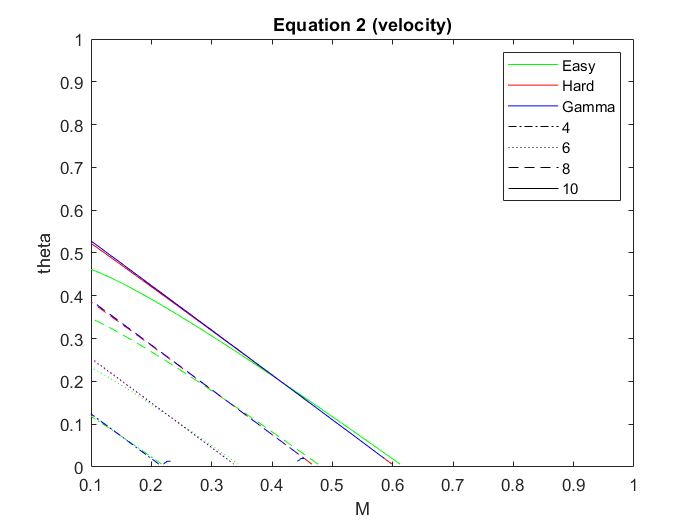

% Initiate
alpha   = 0.1;
beta    = 0.7;
C       = 0.98;
V = [4, 6, 8, 10];
ls = {'-.',':','--','-'};

% Loop for different velocities 
figure()
for i=1:length(V)
v=V(i);

syms M theta
% Make equations
[v_eqn_EasyLevel, v_eqn_HardLevel,v_eqn_GammaLevel] = make_equations_v(M,theta,v,alpha,beta,C);

% Plot
p1 = fimplicit(v_eqn_EasyLevel,'Color','g','LineStyle',ls{i});
hold on
p2 = fimplicit(v_eqn_HardLevel,'Color','r','LineStyle',ls{i});
hold on
p3 = fimplicit(v_eqn_GammaLevel,'Color','b','LineStyle',ls{i});
end

% Plot stuff just to make legend
hold on
st1 = plot([-2,-1],[-2,-1],'Color','k','LineStyle','-.');
hold on
st2 = plot([-2,-1],[-2,-1],'Color','k','LineStyle',':');
hold on
st3 = plot([-2,-1],[-2,-1],'Color','k','LineStyle','--');
hold on
st4 = plot([-2,-1],[-2,-1],'Color','k','LineStyle','-');

xlim([0.1,1])
ylim([0,1])
xlabel('M')
ylabel('theta')
legend([p1,p2,p3,st1,st2,st3,st4],{'Easy','Hard','Gamma','4','6','8','10'})
title('Equation 2 (velocity)')

**Comments:**

Here the problem that appeared with equation 1, of the easy approximation don't follow the ground truth doesn't happen, as we already saw before.

## EQUATION 1 & 2 - Plot in function of M and theta and fixed g

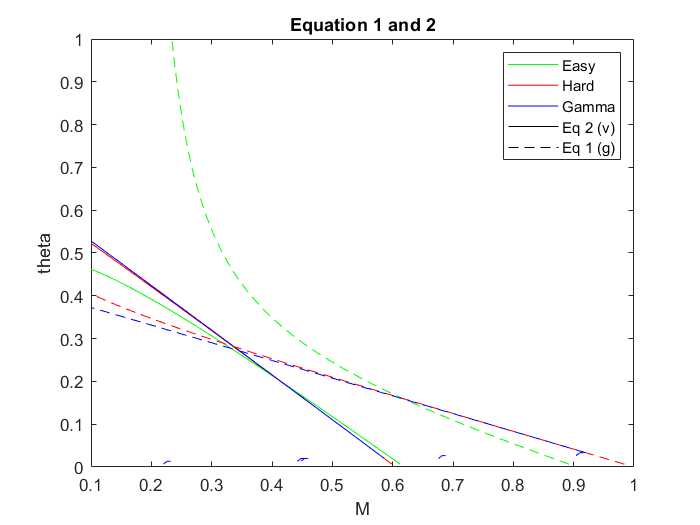

% Initiate
alpha   = 0.1;
beta    = 0.7;
A       = 1.02; 
C       = 0.98; 
g       = 0.7;
v       = 10;

figure()
syms M theta

% Make equations
[v_eqn_EasyLevel, v_eqn_HardLevel,v_eqn_GammaLevel] = make_equations_v(M,theta,v,alpha,beta,C);
[g_eqn_EasyLevel_raw, g_eqn_HardLevel,g_eqn_GammaLevel] = make_equations_g(M,theta,g,alpha,beta,A);

% Plot
p1 = fimplicit(v_eqn_EasyLevel,'Color','g','LineStyle','-');
hold on
p2 = fimplicit(v_eqn_HardLevel,'Color','r','LineStyle','-');
hold on
p3 = fimplicit(v_eqn_GammaLevel,'Color','b','LineStyle','-');
hold on 
p4 = fimplicit(g_eqn_EasyLevel_raw,'Color','g','LineStyle','--');
hold on
fimplicit(g_eqn_HardLevel,'Color','r','LineStyle','--');
hold on
fimplicit(g_eqn_GammaLevel,'Color','b','LineStyle','--');
hold on
st1 = plot([-2,-1],[-2,-1],'Color','k','LineStyle','-');
hold on
st2 = plot([-2,-1],[-2,-1],'Color','k','LineStyle','--');

xlim([0.1,1])
ylim([0,1])
xlabel('M')
ylabel('theta')
legend([p1,p2,p3,st1,st2],{'Easy','Hard','Gamma','Eq 2 (v)','Eq 1 (g)'})
title('Equation 1 and 2')

**Comments:**

We want to find the intersection between these 2 equations. They depend a lot on the velocity and g-ratios given.

##  EQUATION 1 & 2 - Plot in function of M and theta, several g and v

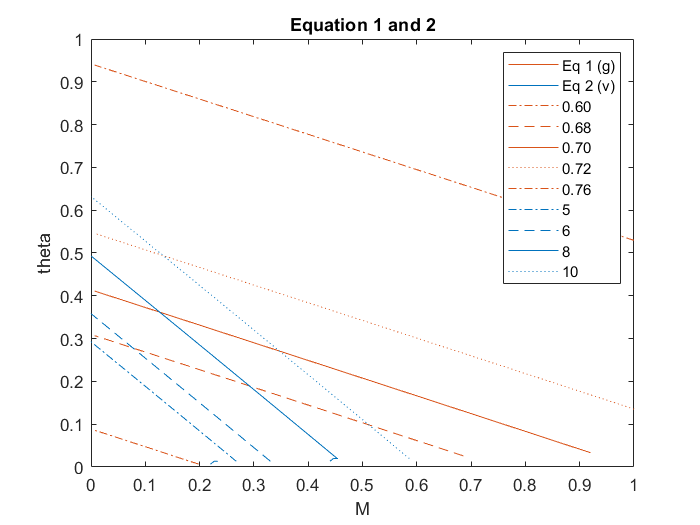

% Initiate
alpha   = 0.1;
beta    = 0.70;
A       = 1.02; 
C       = 0.98; 
G = [0.6, 0.68, 0.70, 0.72, 0.76];
V = [5, 6, 8, 10];
ls = {'-.','--','-',':','-.'};

% Loop for different g ratios
figure()
for i=1:length(G)
    g=G(i);
    syms M theta

    % Make equations
    [g_eqn_EasyLevel_raw, g_eqn_HardLevel,g_eqn_GammaLevel] = make_equations_g(M,theta,g,alpha,beta,A);

    % Plot
    fimplicit(g_eqn_GammaLevel,'Color',[0.8500, 0.3250, 0.0980],'LineStyle',ls{i});
    hold on
end


 for i=1:length(V)
        v=V(i);
        syms M theta
        
        % Make equations
        [v_eqn_EasyLevel, v_eqn_HardLevel,v_eqn_GammaLevel] = make_equations_v(M,theta,v,alpha,beta,C);

        % Plot
        fimplicit(v_eqn_GammaLevel,'Color',[0, 0.4470, 0.7410],'LineStyle',ls{i});
        hold on
 end
        
% Plot stuff just to make legend
hold on
p1 = plot([-2,-1],[-2,-1],'Color',[0.8500, 0.3250, 0.0980],'LineStyle','-');
hold on
p2 = plot([-2,-1],[-2,-1],'Color',[0, 0.4470, 0.7410],'LineStyle','-');
hold on
st1 = plot([-2,-1],[-2,-1],'LineStyle','-.','Color',[0.8500, 0.3250, 0.0980]);
hold on
st2 = plot([-2,-1],[-2,-1],'LineStyle','--','Color',[0.8500, 0.3250, 0.0980]);
hold on
st3 = plot([-2,-1],[-2,-1],'LineStyle','-','Color',[0.8500, 0.3250, 0.0980]);
hold on
st4 = plot([-2,-1],[-2,-1],'LineStyle',':','Color',[0.8500, 0.3250, 0.0980]);
hold on
st5 = plot([-2,-1],[-2,-1],'LineStyle','-.','Color',[0.8500, 0.3250, 0.0980]);
hold on
st6 = plot([-2,-1],[-2,-1],'LineStyle','-.','Color',[0, 0.4470, 0.7410]);
hold on
st7 = plot([-2,-1],[-2,-1],'LineStyle','--','Color',[0, 0.4470, 0.7410]);
hold on
st8 = plot([-2,-1],[-2,-1],'LineStyle','-','Color',[0, 0.4470, 0.7410]);
hold on
st9 = plot([-2,-1],[-2,-1],'LineStyle',':','Color',[0, 0.4470, 0.7410]);
hold on

xlim([0,1])
ylim([0,1])
xlabel('M')
ylabel('theta')
legend([p1,p2,st1,st2,st3,st4,st5,st6,st7,st8,st9],{'Eq 1 (g)','Eq 2 (v)','0.60', '0.68', '0.70', '0.72', '0.76','5','6','8','10'})
title('Equation 1 and 2')

**Comments**:

Tiny differences in the g-ratio (0.02 for example) can lead to big differences in the Mode and Theta pairs, respectively 0.15 and and 0.11 approximatly. 

This will happen in real life, since we would have some noise in the g-ratios. See next section.

## EQUATION 1 & 2 - Sensibility to noise

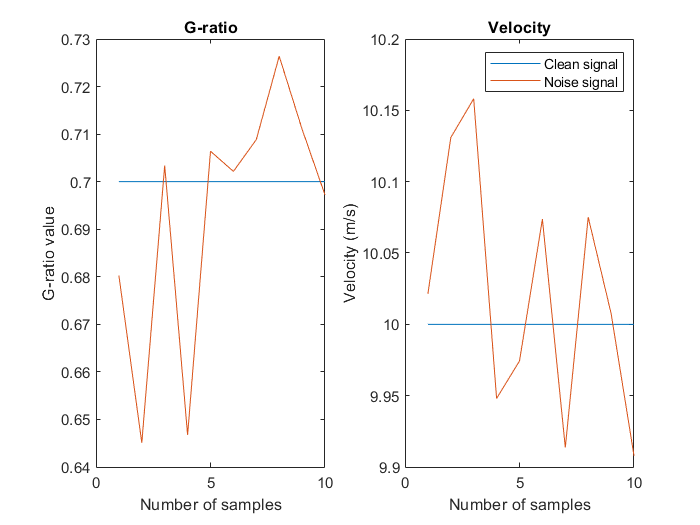

% Initiate 
alpha   = 0.1;
beta    = 0.7;
G_raw   = 0.7*ones(10,1);
V_raw   = 10*ones(10,1);
G       = awgn(G_raw,30);
V       = awgn(V_raw,20);

figure()
subplot(1,2,1)
plot(1:10,G_raw)
hold on
plot(1:10,G)
title('G-ratio')
xlabel('Number of samples')
ylabel('G-ratio value')
subplot(1,2,2)
plot(1:10,V_raw)
hold on
plot(1:10,V)
title('Velocity')
xlabel('Number of samples')
ylabel('Velocity (m/s)')
legend('Clean signal','Noise signal')


S1 = [];
S2 = [];

for i=1:length(G)
    g   = G(i);
    v   = V(i);
    % Make equations
    syms M theta
    [v_eqn_EasyLevel, v_eqn_HardLevel,v_eqn_GammaLevel] = make_equations_v(M,theta,v,alpha,beta,C);
    [g_eqn_EasyLevel_raw, g_eqn_HardLevel,g_eqn_GammaLevel] = make_equations_g(M,theta,g,alpha,beta,A);

    % Solve equations
    [s1, s2]    = vpasolve([g_eqn_GammaLevel v_eqn_GammaLevel],[M theta],[0 1; 0 1]);
    S1          = [S1; double(s1)];
    S2          = [S2; double(s2)];
end

meanMode    = mean(S1);
meanTheta   = mean(S2);
stdMode     = std(S1);
stdTheta    = std(S2);

sprintf('Mean mode is: %.02f +/- %.02f',meanMode,stdMode)

ans = 'Mean mode is: 0.30 +/- 0.13'

sprintf('Mean Theta is: %.02f +/- %.02f',meanTheta,stdTheta)

ans = 'Mean Theta is: 0.32 +/- 0.13'

**Comments:**

If we increase the noise level, the mean and std deviations of mode and theta can get quite high. This method is not so efficient as trying to solve all with all the g's at once, using a least square method. To handle this go to the other script.

## EQUATION 1 & 2 - Sensibility to Alpha and Beta

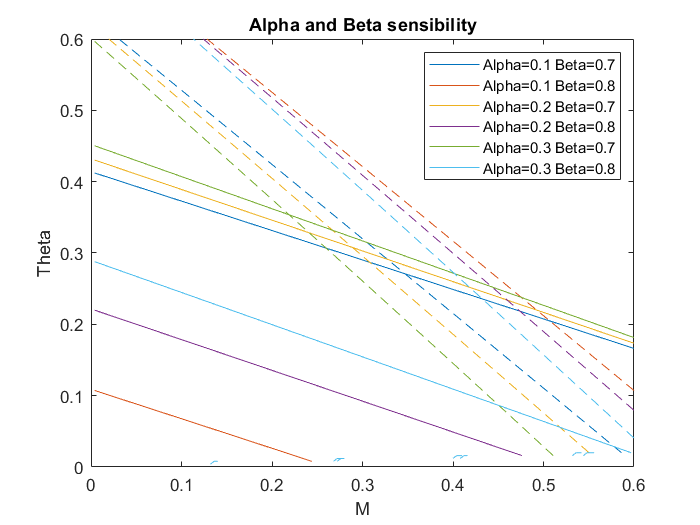

% Initiate
A       = 1.02; 
C       = 0.98; 
Alpha   = [0.1, 0.2, 0.3];
Beta    = [0.7, 0.8];
Color_list  = [0, 0.4470, 0.7410; 0.8500, 0.3250, 0.0980; 0.9290, 0.6940, 0.1250; 0.4940, 0.1840, 0.5560; 0.4660, 0.6740, 0.1880; 0.3010, 0.7450, 0.9330; 0.6350, 0.0780, 0.1840; 0.4660, 0.6740, 0.1880];          	
lgn = cell(6,1);
k       = 1;

% Loop for different alphas e betas
figure()
for i=1:length(Alpha)
    alpha = Alpha(i);
    for j=1:length(Beta)
        beta = Beta(j);
        % Make equations and plot for limiting g's or just on g for better
        % understanding
%         syms M theta
%         g = 0.6;
%         [~, ~,g_eqn_GammaLevel] = make_equations_g(M,theta,g,alpha,beta,A);
%         fimplicit(g_eqn_GammaLevel,'Color',Color_list(k,:),'LineStyle','-');
%         hold on
        syms M theta
        g = 0.7;
        [~, ~,g_eqn_GammaLevel] = make_equations_g(M,theta,g,alpha,beta,A);
        fimplicit(g_eqn_GammaLevel,'Color',Color_list(k,:),'LineStyle','-');
        hold on
        syms M theta
%         v = 5;
%         [~, ~,v_eqn_GammaLevel] = make_equations_v(M,theta,v,alpha,beta,C);
%         fimplicit(v_eqn_GammaLevel,'Color',Color_list(k,:),'LineStyle','--');
%         hold on
        v = 10;
        [~, ~,v_eqn_GammaLevel] = make_equations_v(M,theta,v,alpha,beta,C);
        fimplicit(v_eqn_GammaLevel,'Color',Color_list(k,:),'LineStyle','--');
        hold on   
        lgn{k} = strcat('Alpha=',num2str(alpha),' Beta=',num2str(beta));
        k = k+1;
    end
end

% Plot stuff just to make legend
st1 = plot([-2,-1],[-2,-1],'LineStyle','-','Color',Color_list(1,:));
hold on
st2 = plot([-2,-1],[-2,-1],'LineStyle','-','Color',Color_list(2,:));
hold on
st3 = plot([-2,-1],[-2,-1],'LineStyle','-','Color',Color_list(3,:));
hold on
st4 = plot([-2,-1],[-2,-1],'LineStyle','-','Color',Color_list(4,:));
hold on
st5 = plot([-2,-1],[-2,-1],'LineStyle','-','Color',Color_list(5,:));
hold on
st6 = plot([-2,-1],[-2,-1],'LineStyle','-','Color',Color_list(6,:));
hold on


xlim([0,0.6])
ylim([0,0.6])
xlabel('M')
ylabel('Theta')
legend([st1,st2,st3,st4,st5,st6],lgn)
title('Alpha and Beta sensibility')

**Comments**:

When alpha increases, the g-ratio equation, leads to smaller Mode and bigger Theta values. 

When alpha increases, the velocity equation, leads to smaller Mode and bigger Theta values.

When beta increases, the g-ratio equation, leads to bigger Mode and smaller Theta values.

When beta increases, the velocity equation, leads to bigger Mode and smaller Theta values.

For the g-ratio equation, the alpha variation (bwn 0.1 and 0.3) doesn't impact the results that much, a bigger impact has the beta variation of just 0.1, for the velocity equation the same is not true.

To have values around the ones expected from the literature, it seems that we need beta = 0.7 (or at least not 0.8) and an alpha of as low as possible. An alpha = 0 means that the g-ratio is constant and equal to beta.

## EQUATION 1 & 2 - Solve for given g 

% Initiate
alpha   = 0.1;
beta    = 0.7;
A       = 1.02; 
C       = 0.98; 
g       = 0.70;
v       = 10;

% Make equations
syms M theta
[v_eqn_EasyLevel, v_eqn_HardLevel,v_eqn_GammaLevel] = make_equations_v(M,theta,v,alpha,beta,C);
[g_eqn_EasyLevel_raw, g_eqn_HardLevel,g_eqn_GammaLevel] = make_equations_g(M,theta,g,alpha,beta,A);

% Solve equations
[S1, S2] = vpasolve([g_eqn_GammaLevel v_eqn_GammaLevel],[M theta],[0 1; 0 1])

$$S1 = 0.34687755640027278564263081571043$$

$$S2 = 0.27092072701785458718867451685293$$

**Comments:**

This is the way to solve the equations. The graphs shown before is just to get an idea how it behaves.

###  EQUATION 1 & 2 - Solve for our data

% Load files
cd(fullfile(path,'Example_images'))
file = dir('g_ratio.nii');
header = spm_vol(file.name);
gratio = spm_read_vols(header);

file = dir('Occipital_mask_tract.nii');
header = spm_vol(file.name);
tract = spm_read_vols(header);

% Initiate
alpha   = 0.1;
beta    = 0.7;
A       = 1.02; 
C       = 0.98; 
g_map = gratio.*tract;
v       = 10;

for x=1:96
    for y=1:106
        for z=1:70
            if g_map(x,y,z)~= 0 && g_map(x,y,z)> 0.65
                g=g_map(x,y,z);
                % Make equations
                syms M theta
                [v_eqn_EasyLevel, v_eqn_HardLevel,v_eqn_GammaLevel] = make_equations_v(M,theta,v,alpha,beta,C);
                [g_eqn_EasyLevel_raw, g_eqn_HardLevel,g_eqn_GammaLevel] = make_equations_g(M,theta,g,alpha,beta,A);
                % Solve equations
                [S1, S2] = vpasolve([g_eqn_GammaLevel v_eqn_GammaLevel],[M theta],[0.1 0.8; 0 1]);
                sprintf('g-ratio: %.2f, mode: %.2f, theta: %.2f',g,S1,S2)

            end
        end
    end
end

ans = 'g-ratio: 0.66, mode: , theta: '

ans = 'g-ratio: 0.67, mode: 0.57, theta: 0.04'

ans = 'g-ratio: 0.67, mode: 0.58, theta: 0.03'

ans = 'g-ratio: 0.68, mode: 0.48, theta: 0.13'

ans = 'g-ratio: 0.66, mode: , theta: '

ans = 'g-ratio: 0.66, mode: , theta: '

ans = 'g-ratio: 0.67, mode: 0.60, theta: 0.00'

ans = 'g-ratio: 0.67, mode: 0.57, theta: 0.03'

ans = 'g-ratio: 0.65, mode: , theta: '

ans = 'g-ratio: 0.66, mode: , theta: '

ans = 'g-ratio: 0.68, mode: 0.51, theta: 0.10'

ans = 'g-ratio: 0.69, mode: 0.43, theta: 0.18'

ans = 'g-ratio: 0.67, mode: 0.57, theta: 0.03'

ans = 'g-ratio: 0.69, mode: 0.42, theta: 0.19'

ans = 'g-ratio: 0.66, mode: , theta: '

ans = 'g-ratio: 0.69, mode: 0.43, theta: 0.19'

ans = 'g-ratio: 0.67, mode: 0.60, theta: 0.01'

ans = 'g-ratio: 0.65, mode: , theta: '

ans = 'g-ratio: 0.67, mode: 0.60, theta: 0.00'

ans = 'g-ratio: 0.70, mode: 0.34, theta: 0.28'

ans = 'g-ratio: 0.72, mode: 0.14, theta: 0.49'

ans = 'g-ratio: 0.68, mode: 0.53, theta: 0.08'

ans = 'g-ratio: 0.66, mode: , theta: '

ans = 'g-ratio: 0.68, mode: 0.48, theta: 0.14'

ans = 'g-ratio: 0.68, mode: 0.49, theta: 0.12'

ans = 'g-ratio: 0.67, mode: 0.60, theta: 0.01'

ans = 'g-ratio: 0.68, mode: 0.49, theta: 0.12'

ans = 'g-ratio: 0.67, mode: 0.55, theta: 0.06'

ans = 'g-ratio: 0.69, mode: 0.41, theta: 0.21'

ans = 'g-ratio: 0.66, mode: , theta: '

ans = 'g-ratio: 0.67, mode: 0.55, theta: 0.06'

ans = 'g-ratio: 0.69, mode: 0.43, theta: 0.19'

ans = 'g-ratio: 0.70, mode: 0.32, theta: 0.30'

ans = 'g-ratio: 0.68, mode: 0.53, theta: 0.08'

ans = 'g-ratio: 0.68, mode: 0.49, theta: 0.12'

ans = 'g-ratio: 0.68, mode: 0.49, theta: 0.12'

ans = 'g-ratio: 0.68, mode: 0.53, theta: 0.08'

ans = 'g-ratio: 0.69, mode: 0.39, theta: 0.22'

ans = 'g-ratio: 0.71, mode: 0.27, theta: 0.35'

ans = 'g-ratio: 0.68, mode: 0.49, theta: 0.12'

ans = 'g-ratio: 0.67, mode: 0.59, theta: 0.02'

ans = 'g-ratio: 0.69, mode: 0.42, theta: 0.19'

ans = 'g-ratio: 0.70, mode: 0.38, theta: 0.24'

ans = 'g-ratio: 0.69, mode: 0.43, theta: 0.19'

ans = 'g-ratio: 0.71, mode: 0.27, theta: 0.35'

ans = 'g-ratio: 0.69, mode: 0.41, theta: 0.21'

ans = 'g-ratio: 0.68, mode: 0.53, theta: 0.08'

ans = 'g-ratio: 0.70, mode: 0.34, theta: 0.28'

ans = 'g-ratio: 0.73, mode: , theta: '

**Comments:**

This can take a while, but basically we can see that smaller differences in the g-ratio inside these tract would lead to quite big differences inthe mode and theta values that we find. This has to be solved another way. Sometimes is not even possible to find a solution because the velocity that it's being used is not appropriate to that g-ratio.

# Definition of functions in Matlab

### Equation 1 (g-ratio):

function [g_eqn_EasyLevel_raw, g_eqn_HardLevel,g_eqn_GammaLevel] = make_equations_g(M,theta,g,alpha,beta,A)
g_eqn_EasyLevel_raw     = g^2 == beta^2*theta^(2*alpha) ...
    * A*(M/theta)^(2*alpha) ... % Lower limit and factor A
    * (M + 3*theta + 2*(theta^2)/M) ...
    / (M + (3 - 4*alpha)*theta + (2+4*alpha^2-6*alpha)*(theta^2)/M);
g_eqn_HardLevel         = g^2 == beta^2*theta^(2*alpha) ...
    * (M/theta+1/2-alpha)^(2*alpha) ... % Complex limit without factor
    * (M + 3*theta + 2*(theta^2)/M) ...
    / (M + (3 - 4*alpha)*theta + (2+4*alpha^2-6*alpha)*(theta^2)/M);
g_eqn_GammaLevel        = g^2 == beta^2*theta^(2*alpha) ...
    * gamma(M/theta+1)/gamma(M/theta+1-2*alpha) ... % Without approximmation
    * (M + 3*theta + 2*(theta^2)/M) ...
    / (M + (3 - 4*alpha)*theta + (2+4*alpha^2-6*alpha)*(theta^2)/M);
end


### Equation 2 (velocity):

function [v_eqn_EasyLevel, v_eqn_HardLevel,v_eqn_GammaLevel] = make_equations_v(M,theta,v,alpha,beta,C)
v_eqn_EasyLevel     = v == ((2*5.5)/beta)*theta^(1-alpha) ...
    * C*(M/theta)^(-alpha) ... % Lower limit and factor A
    * (M/theta+1-alpha);
v_eqn_HardLevel         = v == ((2*5.5)/beta)*theta^(1-alpha) ...
    * (M/theta+1/2-alpha/2)^(-alpha) ... % Complex limit without factor
    * (M/theta+1-alpha);
v_eqn_GammaLevel        = v == ((2*5.5)/beta)*theta^(1-alpha) ...
    * gamma(M/theta+1-alpha)/gamma(M/theta+1) ... % Without approximmation
    * (M/theta+1-alpha);
end